# Miniprojekt 2 - Fkrevensanalyse af målte vibrationssignaler

## Indledning

## Formål

Bliv fortrolig med diskret Fouriertransformation (DFT), og anvend denne til at analysere frekvensindholdet i forskellige signaler. Bliv fortrolig med Matlab til at håndtere og analysere digitale signaler

### Loading af fil

Vi vil starte med at loade signalet ind i Matlab sammen med dens samplingfrekvens.

load("Opgave2_audiofil_1_1.mat");

### **A. Plot de første 5 sekunder og beskriv hvilke frekvenser som I forventer signalet indeholder ud fra det tidslige plot. Tidsskalaen skal være i sekunder og amplitudeskalaen i volt**

Først laves den korrekte skalering af amplituden, da 1 volt svarer til 100 enheder.

raw_input = raw_input.*0.01;

Først beregnes sample periode tiden med formlen:


$$\textrm{Ts}=\frac{1}{\textrm{Fs}}$$


fs

fs = 25600

Nu da vi har loaded signalet ind, kan vi starte med at plotte de første fem sekunder.

Ts=1/fs

Ts = 3.9063e-05

Nu laves en tidsakse på fem sekunder:

t=0:Ts:5;

Et array over alle elemneter laves:

n=0:length(raw_input)-1;

Signalet kan nu plottes:

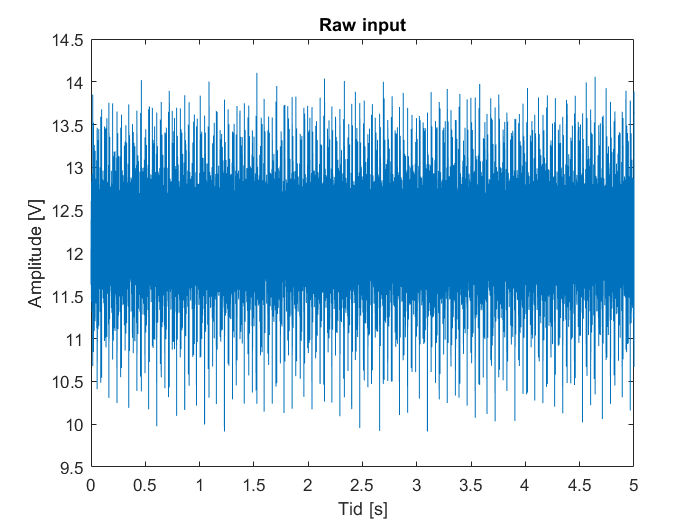

plot(n*Ts,raw_input)
title('Raw input')
xlabel('Tid [s]')
ylabel('Amplitude [V]')
xlim([0 5])
%ylim([(min(raw_input)*1.2) (max(raw_input)*0.8)])
hold off

### **B. Beregn DC middelværdien, AC RMS-værdien, og energien for de første 5 sekunder af signalet.**

N = length(raw_input) % Antal samples

N = 262144

t_5 = t<=5 ; % Tid til og med første 5 sekunder
raw_input5 = raw_input(t_5); % raw_input af de første 5 sekunder
mid = myMean(raw_input5) % Middelværdien

mid = 12.1765

raw_input5AC = raw_input5 - mid; % DC værdien fratrukket
rms = myRMS(raw_input5AC) % RMS-værdien

rms = 0.3278

energi = myEnergy(raw_input5AC) % Energien

energi = 1.3751e+04

### **C. Træk DC middelværdien fra tidssignalet. Den stammer fra forsyningsspændingen og bærer ingen signalinformation (i dette tilfælde).**

Da DC-værdien stammer fra forsyningsspændingen og ingen information har, trækkes den fra tidssignalet.

raw_input = raw_input-mid;

Signalet uden DC-værdien plottes:

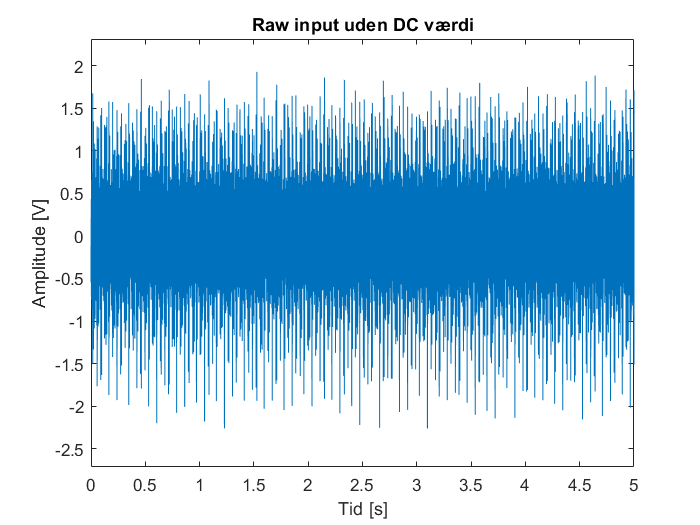

plot(n*Ts,raw_input)
title('Raw input uden DC værdi')
xlabel('Tid [s]')
ylabel('Amplitude [V]')
xlim([0 5])
ylim([-2.7145 2.3125])
hold off

### D. Lav frekvenstransformation på de første 5 sekunder af signalet og vis frekvensspektret.

N5 = length(raw_input5AC)

N5 = 128001

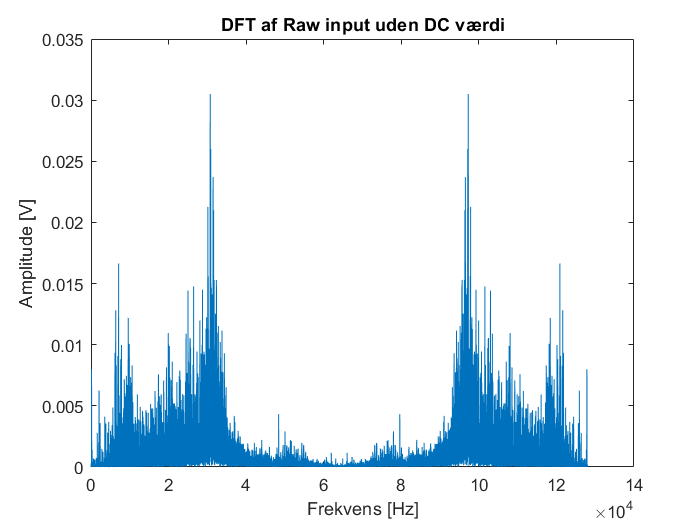

k = 0:N5-1; % Frekvens pins
DFT = fft(raw_input5AC,N5); % DFT
DFT = DFT .*2/N5;
plot(k, abs(DFT)) % Plot af DFT 
title('DFT af Raw input uden DC værdi')
xlabel('Frekvens [Hz]')
ylabel('Amplitude [V]')
hold off